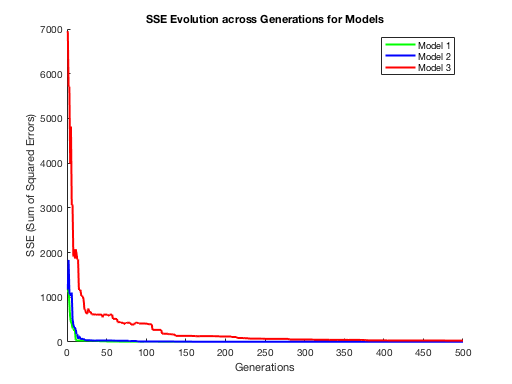

clc;
clear;

% 1. Load and preprocess the data
rawData = csvread('SalData.csv', 1, 0);  % Skip the header row

% Extract features (v1 to v7) and target (salary)
X = rawData(:, 2:end);  % Inputs (features)
Y = rawData(:, 1);      % Target (Salary)

% 2. Normalize features using Z-score normalization
inputMean = mean(X);
inputStd = std(X);
X_norm = (X - inputMean) ./ inputStd;  % Z-score normalization for features

% Normalize target (salary) as well
salaryMean = mean(Y);
salaryStd = std(Y);
Y_norm = (Y - salaryMean) / salaryStd;  % Z-score normalization for target

% 3. Split the data into training (80%) and test (20%) sets manually
n_samples = size(Y_norm, 1);
splitRatio = 0.8;  % 80% training, 20% testing
n_train = round(splitRatio * n_samples);

% Split the data into training and testing sets
trainInputs = X_norm(1:n_train, :);
trainSalary = Y_norm(1:n_train);
testInputs = X_norm(n_train+1:end, :);
testSalary = Y_norm(n_train+1:end);

% 4. Initialize Genetic Algorithm parameters
populationSize = 100;       % Population size
maxGenerations = 500;       % Number of generations
mutationProb = 0.05;        % Mutation probability
mutationStrength = 0.5;     % Magnitude of mutation
crossoverProb = 0.85;       % Crossover probability

% 5. Define the number of parameters for each model (7, 8, and 15 respectively)
numParams1 = 7;  % Model 1 parameters
numParams2 = 8;  % Model 2 parameters (with bias)
numParams3 = 15; % Model 3 parameters (quadratic terms + bias)

% 6. Initialize the population for each model (randomized between -1 and 1)
popModel1 = rand(populationSize, numParams1) * 2 - 1;
popModel2 = rand(populationSize, numParams2) * 2 - 1;
popModel3 = rand(populationSize, numParams3) * 2 - 1;

% 7. Define fitness functions with L2 regularization
regularizationStrength = 0.05;

fitnessFunc1 = @(params) calculateFitness1(params, trainInputs, trainSalary, regularizationStrength);
fitnessFunc2 = @(params) calculateFitness2(params, trainInputs, trainSalary, regularizationStrength);
fitnessFunc3 = @(params) calculateFitness3(params, trainInputs, trainSalary, regularizationStrength);

% 8. Run the genetic algorithm for each model
[model1History, bestParams1] = evolveGA(popModel1, fitnessFunc1, maxGenerations, mutationProb, mutationStrength, crossoverProb);
[model2History, bestParams2] = evolveGA(popModel2, fitnessFunc2, maxGenerations, mutationProb, mutationStrength, crossoverProb);
[model3History, bestParams3] = evolveGA(popModel3, fitnessFunc3, maxGenerations, mutationProb, mutationStrength, crossoverProb);

% 9. Plot the SSE over generations for each model
figure;
hold on;
plot(1:maxGenerations, model1History, 'g-', 'LineWidth', 2);
plot(1:maxGenerations, model2History, 'b-', 'LineWidth', 2);
plot(1:maxGenerations, model3History, 'r-', 'LineWidth', 2);
xlabel('Generations');
ylabel('SSE (Sum of Squared Errors)');
title('SSE Evolution across Generations for Models');
legend('Model 1', 'Model 2', 'Model 3');
hold off;


% 10. Display the optimized parameters for each model
disp('Best Parameters for Model 1:');

Best Parameters for Model 1:


disp(bestParams1);

    0.1184    0.6935   -0.2521    0.6212    0.0012    0.0072    0.2305



disp('Best Parameters for Model 2:');

Best Parameters for Model 2:


disp(bestParams2);

    0.1170    0.7055   -0.2463    0.6156    0.0032    0.0269    0.2035   -0.0066



disp('Best Parameters for Model 3:');

Best Parameters for Model 3:


disp(bestParams3);

  Columns 1 through 13

    0.1580    0.5250   -0.3582    0.6233    0.0091   -0.0586    0.3897   -0.0341    0.0215    0.0249    0.0278    0.0085    0.0326

  Columns 14 through 15

   -0.0430   -0.0707




% 11. Evaluate the models on the test set
testPredictions1 = predictModel1(bestParams1, testInputs);
testPredictions2 = predictModel2(bestParams2, testInputs);
testPredictions3 = predictModel3(bestParams3, testInputs);

% 12. Denormalize the test predictions and actual salaries
testPredictions1 = testPredictions1 * salaryStd + salaryMean;
testPredictions2 = testPredictions2 * salaryStd + salaryMean;
testPredictions3 = testPredictions3 * salaryStd + salaryMean;
testSalary = testSalary * salaryStd + salaryMean;  % Denormalize the true test salaries

% 13. Calculate SSE for the test set for each model
sseTest1 = sum((testPredictions1 - testSalary).^2);
sseTest2 = sum((testPredictions2 - testSalary).^2);
sseTest3 = sum((testPredictions3 - testSalary).^2);

% Display SSE for each model
fprintf('Test SSE for Model 1: %.4f\n', sseTest1);

Test SSE for Model 1: 287242817.3933


fprintf('Test SSE for Model 2: %.4f\n', sseTest2);

Test SSE for Model 2: 302556805.2028


fprintf('Test SSE for Model 3: %.4f\n', sseTest3);

Test SSE for Model 3: 1547557496.0735



% 14. Identify the best model based on the lowest SSE on the test set
[sseValues, bestModelIdx] = min([sseTest1, sseTest2, sseTest3]);

fprintf('The best model based on the lowest SSE is Model %d with an SSE of %.4f\n', bestModelIdx, sseValues);

The best model based on the lowest SSE is Model 1 with an SSE of 287242817.3933



% 15. Load evaluation data from Evaluation.csv and normalize it
evalData = csvread('Evaluation.csv', 1, 0);  % Skip header row
evalDataNorm = (evalData - inputMean) ./ inputStd;  % Normalize with training data mean/std

% 16. Predict salaries for the evaluation dataset for all three models
evalPred1 = predictModel1(bestParams1, evalDataNorm);
evalPred2 = predictModel2(bestParams2, evalDataNorm);
evalPred3 = predictModel3(bestParams3, evalDataNorm);

% 17. Denormalize the predictions for all three models
evalPred1 = evalPred1 * salaryStd + salaryMean;
evalPred2 = evalPred2 * salaryStd + salaryMean;
evalPred3 = evalPred3 * salaryStd + salaryMean;

% 18. Save the predictions for all three models to CSV files
csvwrite('Eval_Pred_Model1.csv', evalPred1);
csvwrite('Eval_Pred_Model2.csv', evalPred2);
csvwrite('Eval_Pred_Model3.csv', evalPred3);
disp('Predictions for all models saved to CSV files.');

Predictions for all models saved to CSV files.



%% Fitness and Prediction Functions
% Fitness function for Model 1
function sse = calculateFitness1(params, X, Y, regFactor)
    predictions = X * params(:);  % Linear model
    sse = sum((predictions - Y).^2) + regFactor * sum(params.^2);  % L2 regularization
end

% Fitness function for Model 2
function sse = calculateFitness2(params, X, Y, regFactor)
    predictions = X * params(1:7)' + params(8);  % Linear with bias term
    sse = sum((predictions - Y).^2) + regFactor * sum(params.^2);  % L2 regularization
end

% Fitness function for Model 3
function sse = calculateFitness3(params, X, Y, regFactor)
    predictions = X * params(1:7)';  % Linear terms
    for i = 1:7
        predictions = predictions + params(i+7) * (X(:, i).^2);  % Add quadratic terms
    end
    predictions = predictions + params(15);  % Bias term
    sse = sum((predictions - Y).^2) + regFactor * sum(params.^2);  % L2 regularization
end

% Prediction function for Model 1
function predictions = predictModel1(params, X)
    predictions = X * params(:);  % Linear model
end

% Prediction function for Model 2
function predictions = predictModel2(params, X)
    predictions = X * params(1:7)' + params(8);  % Linear with bias term
end

% Prediction function for Model 3
function predictions = predictModel3(params, X)
    predictions = X * params(1:7)';  % Linear terms
    for i = 1:7
        predictions = predictions + params(i+7) * (X(:, i).^2);  % Quadratic terms
    end
    predictions = predictions + params(15);  % Bias term
end

%% Genetic Algorithm Function
function [history, bestParams] = evolveGA(population, fitnessFunc, generations, mutationProb, mutationStrength, crossoverProb)
    popSize = size(population, 1);  % Population size
    numParams = size(population, 2);  % Number of parameters per individual
    history = zeros(generations, 1);  % SSE history over generations

    for gen = 1:generations
        % Step 1: Evaluate fitness
        fitnessScores = arrayfun(@(i) fitnessFunc(population(i, :)), 1:popSize);
        [minFitness, bestIdx] = min(fitnessScores);  % Find best fitness
        bestParams = population(bestIdx, :);  % Best parameters
        history(gen) = minFitness;  % Track best SSE

        % Step 2: Selection (Tournament Selection)
        selectedPopulation = population(tournamentSelection(fitnessScores, popSize), :);

        % Step 3: Crossover
        for i = 1:2:popSize
            if rand < crossoverProb
                crossoverPoint = randi([1, numParams - 1]);  % Random crossover point
                temp = selectedPopulation(i, crossoverPoint+1:end);
                selectedPopulation(i, crossoverPoint+1:end) = selectedPopulation(i+1, crossoverPoint+1:end);
                selectedPopulation(i+1, crossoverPoint+1:end) = temp;
            end
        end

        % Step 4: Mutation
        for i = 1:popSize
            if rand < mutationProb
                mutationIdx = randi(numParams);  % Random mutation point
                selectedPopulation(i, mutationIdx) = selectedPopulation(i, mutationIdx) + mutationStrength * randn;
            end
        end

        % Step 5: Update population
        population = selectedPopulation;
    end
end

% Tournament Selection Function
function selectedIdx = tournamentSelection(fitnessScores, popSize)
    selectedIdx = zeros(1, popSize);  % Initialize selected indices
    for i = 1:popSize
        competitors = randi(popSize, 2, 1);  % Pick two random individuals
        if fitnessScores(competitors(1)) < fitnessScores(competitors(2))
            selectedIdx(i) = competitors(1);  % Select the one with better fitness
        else
            selectedIdx(i) = competitors(2);
        end
    end
end
